# Lab 1: Sampled-Data Systems are Different

Pranshu Malik (`1004138916`) and Varun Sampat (`1003859602`)

In this lab we explore how the discretization can result in different <>... Continuous-time (CT) systems and Discrete-time (DT) systems, particularly linear time-invariant (LTI) systems. We will start with exploring CT systems to DT through sampling. Sampling Continuous Time Signals. after which we will do <part 2>, followed by <part 3>.

## 1. Aliasing

Consider the CT LTI plant with transfer function $G(s) = \frac{1}{s^2 + 0.8s + 1}$. Plot $||G(j\Omega)||$ and $\angle G(j\Omega)$ over frequencies: $\Omega \in (0, 6]  \text{ [rad/s]}$. 

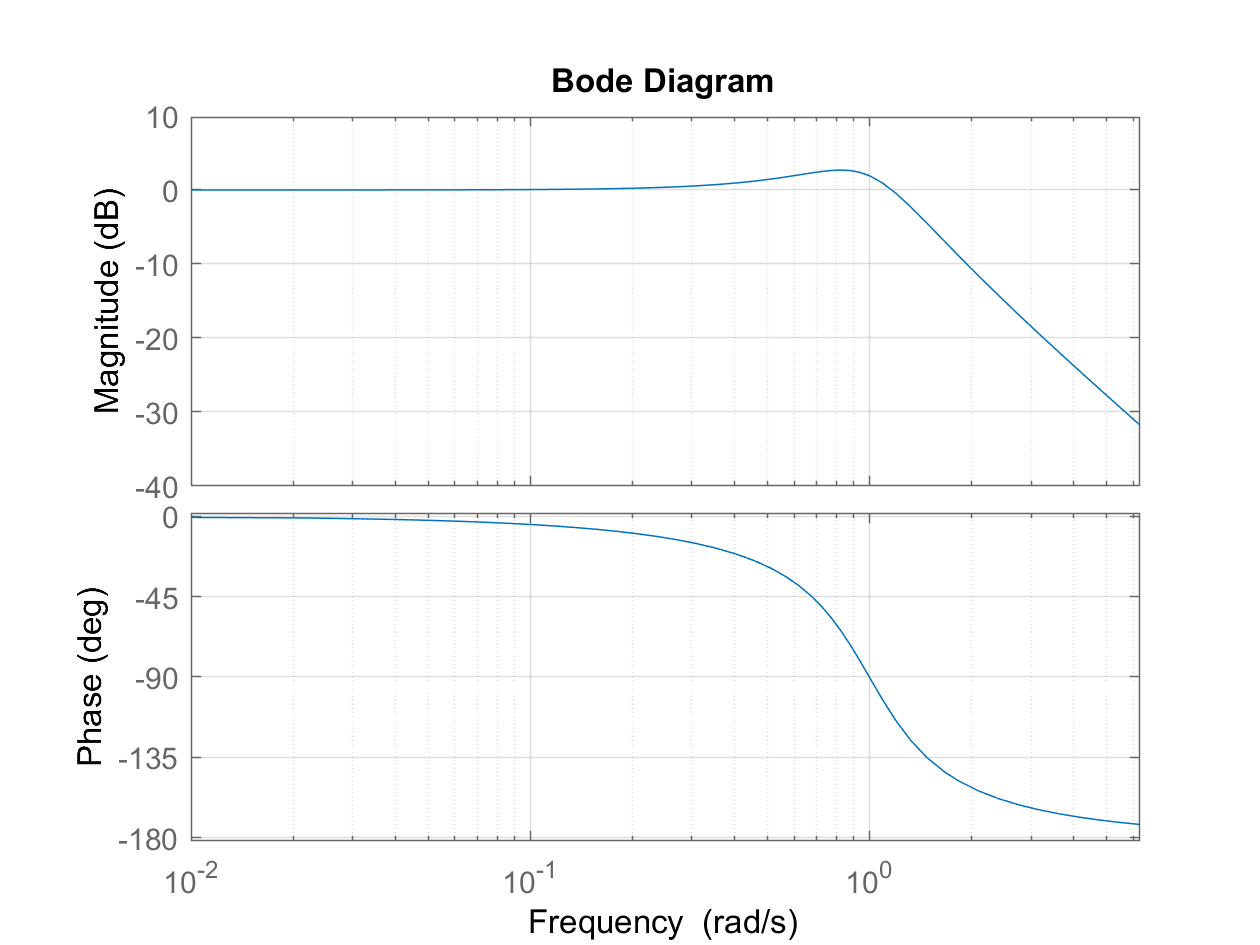

Gs = tf(1, [1 0.8 1]);   % plant transfer function
bodeplot(Gs, {0, 2*pi}); % bode plot of G(s)
grid on;

Now, we sample the $g(t)$ to get $g(kT_s)$ where $T_s$ is the sampling interval. Then, we get: $G(e^{j\omega}) = \frac{1}{T_s}\sum_k G\left( j \left(\frac{\omega}{T_s}-\frac{2\pi k}{T_s}\right)\right)$ where $G(j\Omega)$ is the CTFT of impulse response $g(t)$ and $\omega \text{ [rad]} = \Omega \text{ [rad/s] } T_s$ is the normalized angular frequency.

G(z) is given by: $G(z) = Z\Big[\mathcal{S}\big(\mathcal{L}^{-1}[G(s)]\big)\Big]$.

% sample the CT impulse response of the plant to get its DTFT
Ts = 1;
Gz = c2d(Gs, Ts, 'impulse') % discretized impulse response, g(t) <-> G(z)


Gz =
 
   0.5803 z - 3.222e-17
  -----------------------
  z^2 - 0.8159 z + 0.4493
 
Sample time: 1 seconds
Discrete-time transfer function.



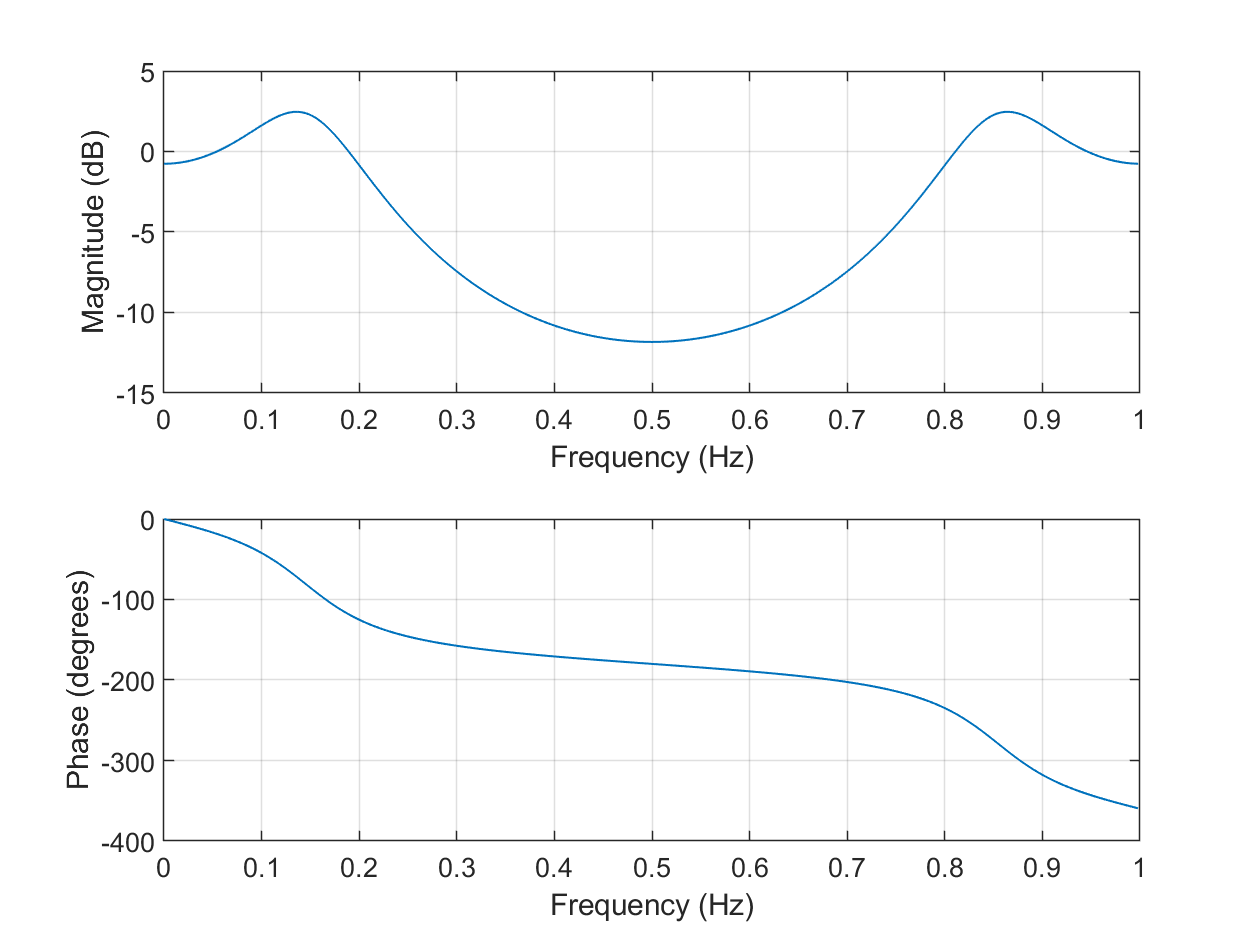

% frequency response plots of G(z)
figure;
freqz(Gz.Numerator{:}, Gz.Denominator{:}, 512, 'whole', 1/Ts);
grid on;

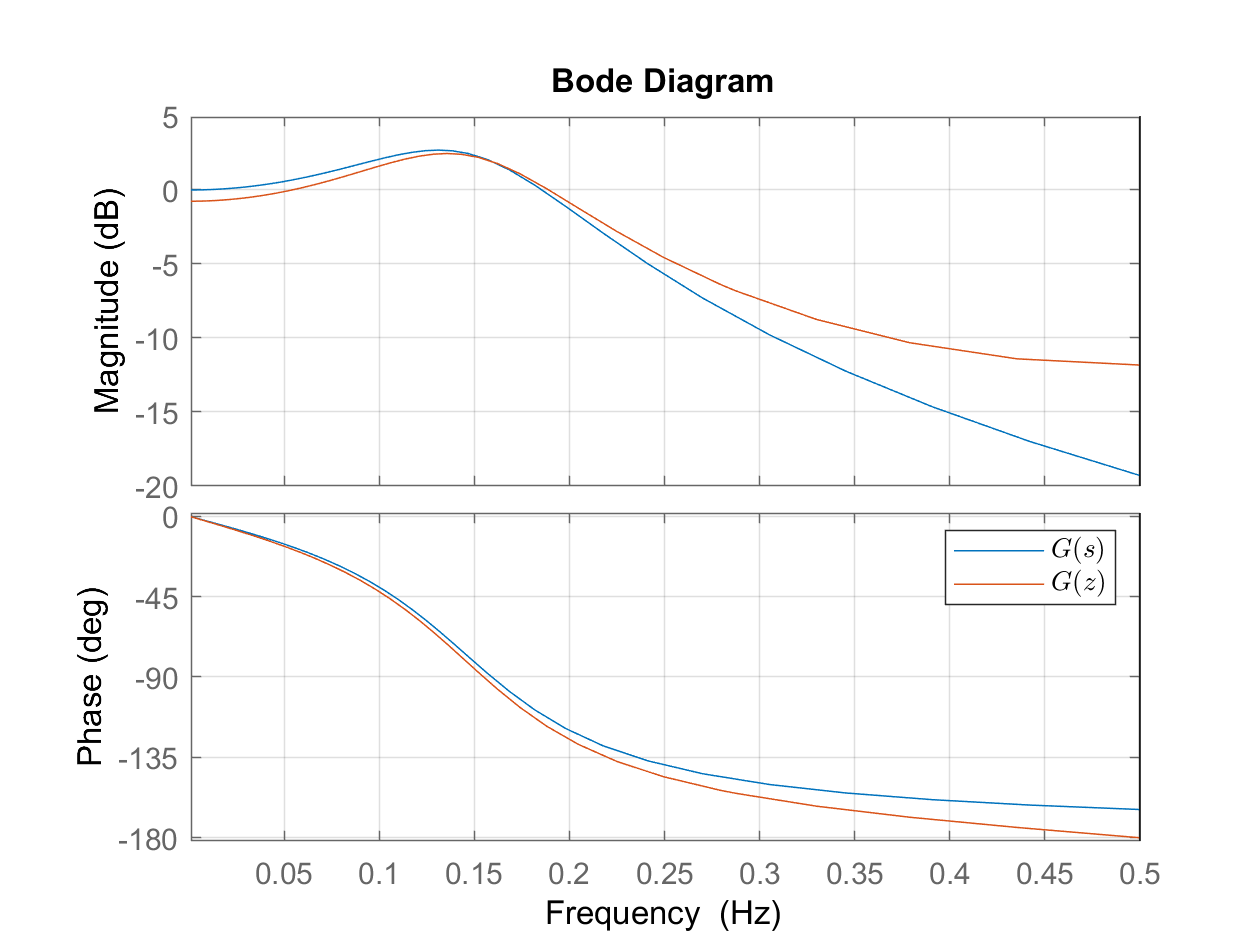

% since Ts = 1, we can use bodeplot(.) to overlay G(s) and G(z)
figure;
bp = bodeplot(Gs, Gz, {0, pi}); % bode plot of G(z) and G(s)
setoptions(bp,'FreqScale','linear','FreqUnits','Hz','Grid','on');
set(legend('$G(s)$', '$G(z)$'), 'Interpreter', 'latex');

We can also discretize the system, or the net transfer function (that naturally includes the hold and sample blocks) as Gd(z).

It is given by: $G_d(z) = \frac{z-1}{z}Z\bigg[\mathcal{S}\Big(\mathcal{L}^{-1}\Big[\frac{G(s)}{s}\Big]\Big)\bigg]$.

% discretized transfer function in state-space representation
sysc     = ss(Gs);
[Ad, Bd] = c2d(sysc.A, sysc.B, Ts)

Ad =     0.1758   -0.5803
    0.5803    0.6401


Bd =     0.5803
    0.3599


% discretized transfer function of the plant, Gd(z)
sysd = ss(Ad, Bd, sysc.C, sysc.D, Ts);
Gd   = tf(sysd)


Gd =
 
     0.3599 z + 0.2735
  -----------------------
  z^2 - 0.8159 z + 0.4493
 
Sample time: 1 seconds
Discrete-time transfer function.



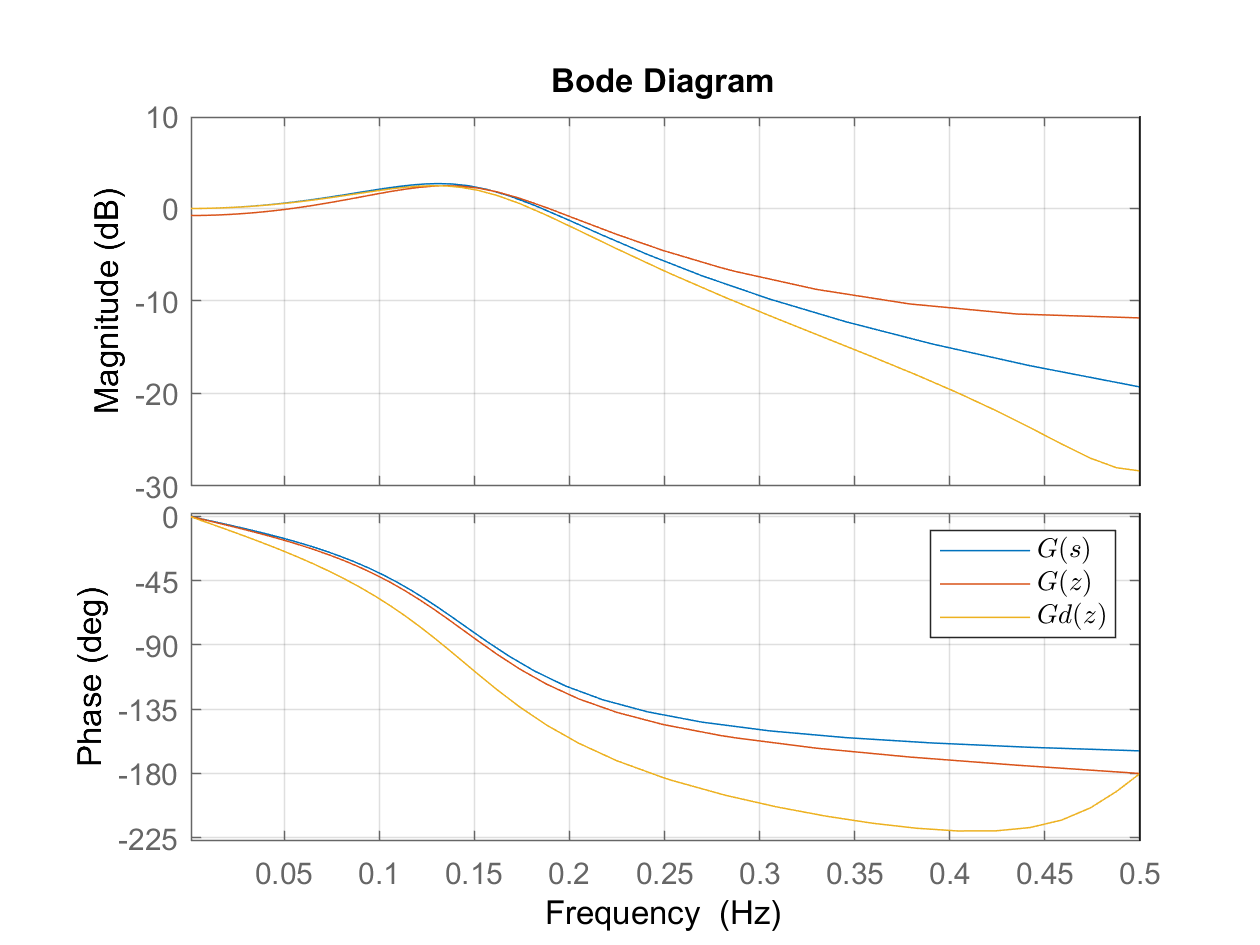

% bode plots of G(s), G(z), and Gd(z)
% again using bodeplot(.) option since Ts = 1; can use freqz if Ts != 1
figure;
dp = bodeplot(Gs, Gz, Gd, {0, pi});
setoptions(dp,'FreqScale','linear','FreqUnits','Hz','Grid','on');
set(legend('$G(s)$', '$G(z)$', '$Gd(z)$'), 'Interpreter', 'latex');

## 2. Effects of Sample and Hold on Control Design

G = tf(1, [0.5 1], 'InputDelay', 0.5)


G =
 
                    1
  exp(-0.5*s) * ---------
                0.5 s + 1
 
Continuous-time transfer function.



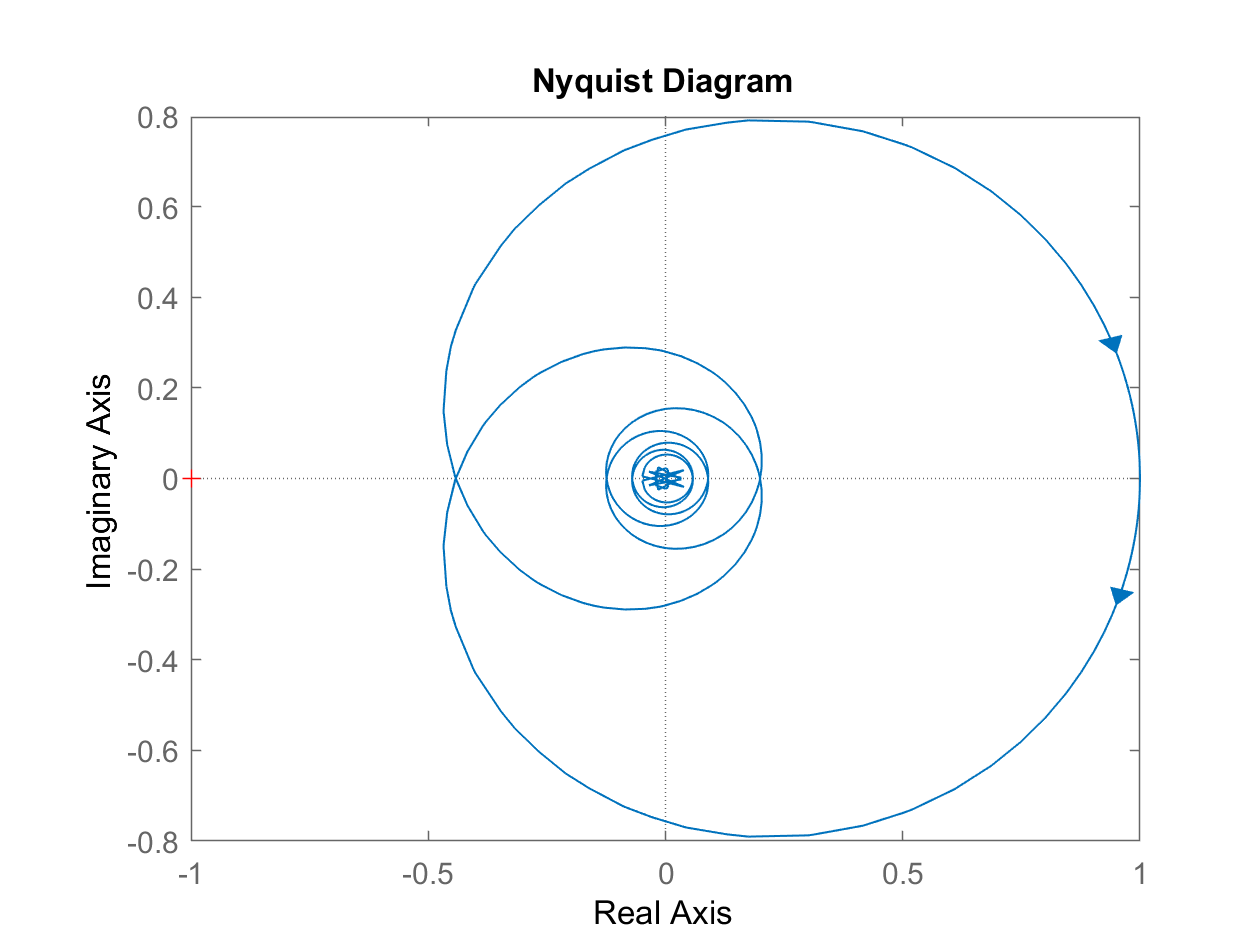

nyquist(G)

**2.1 Estimating Zero-Order Hold Time Delay as Transport Delay**

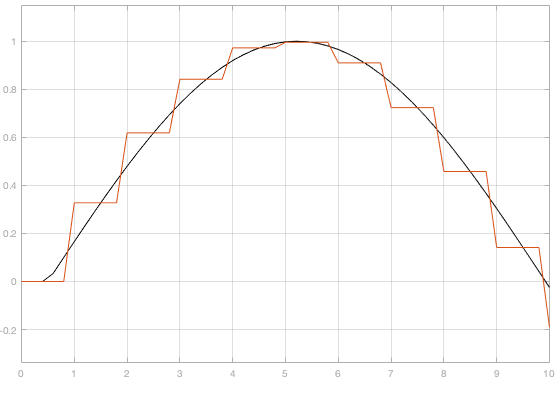

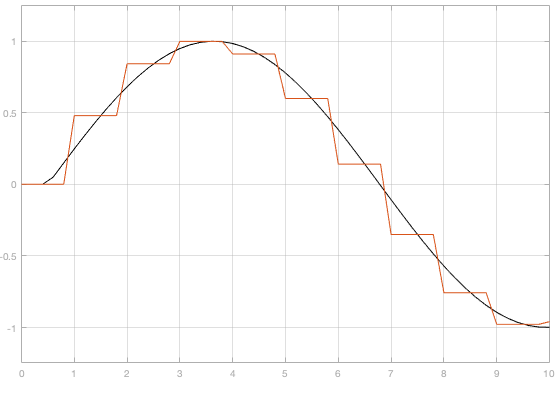

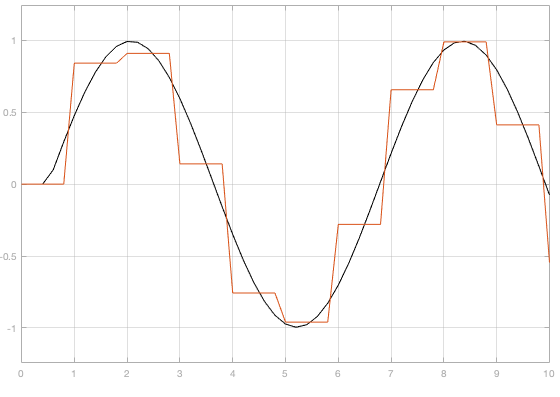

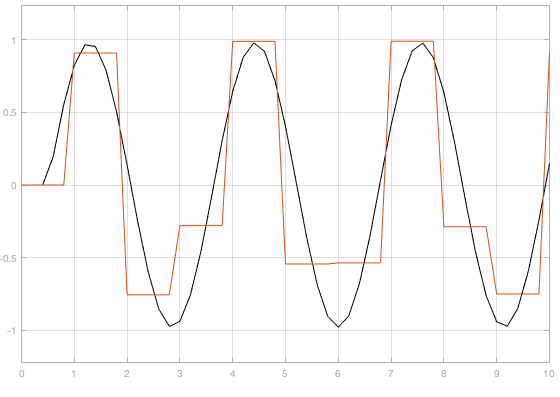

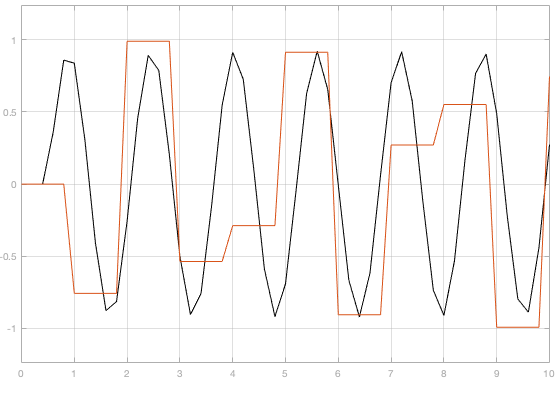

**2.1 Plant Stablity and Feedback Control**

**2.(i) Nyquist plot and stablity **

G = tf(1, [0.5 1], 'InputDelay', 0.5)


G =
 
                    1
  exp(-0.5*s) * ---------
                0.5 s + 1
 
Continuous-time transfer function.



% alternatively
% s = tf('s');
% G = exp(-0.5*s)/(0.5*s+1)
% nyquist(G)

To determine whether the closed loop system is stable, <**WRITE**>

For stability, $-\frac{1}{k}<\;\;-0\ldotp 442$ leading to $k<2\ldotp 262$

But $-\frac{1}{k}<1\;$, leading to $k>-1$

Hence, using the Nyquist plot, the range of values for $k$ that would result in stability is:


$$-1<k<2\ldotp 262$$


**2.(ii) Apply feedback control **$u=k\left(r-y\right)$ to **Continuous Plant **$G\left(s\right)$**to experimentally determine **$k$

Keep in mind there is no need for a delayed transfer function, as we will add the transport delay block on Simulink

When the input is a step response $1\left(t\right)$:


$$k=-1\ldotp 1$$


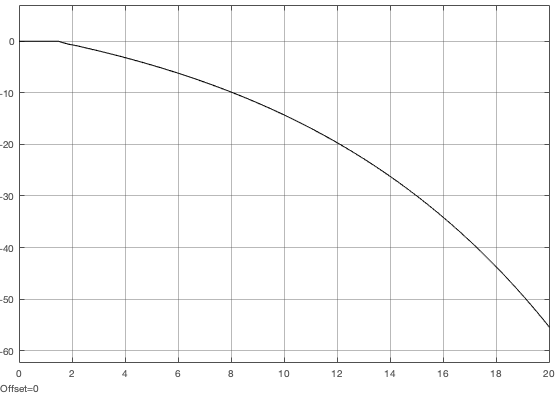


$$k=-0\ldotp 9$$


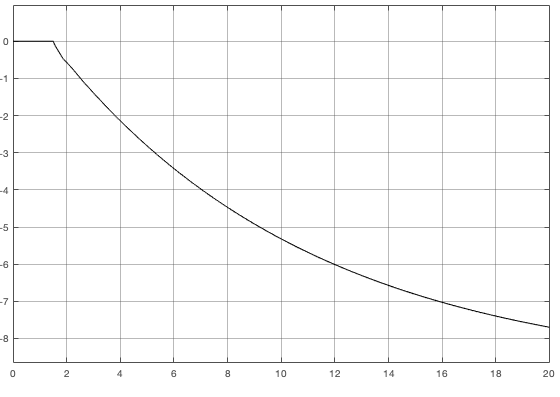


$$k=-0\ldotp 1$$


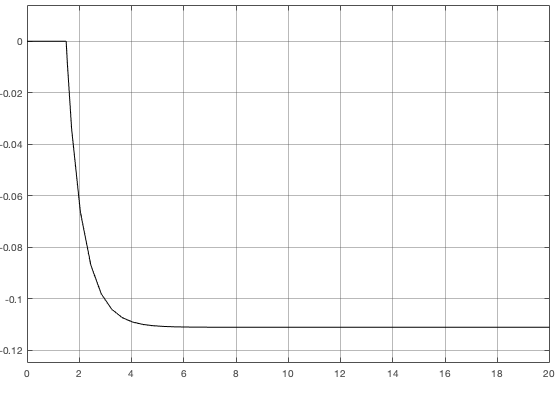


$$k=1$$


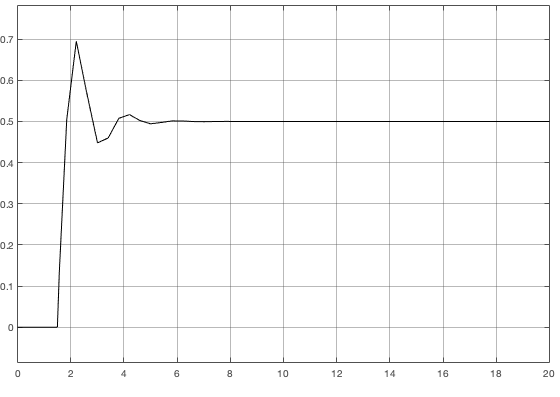


$$k=2\ldotp 6$$


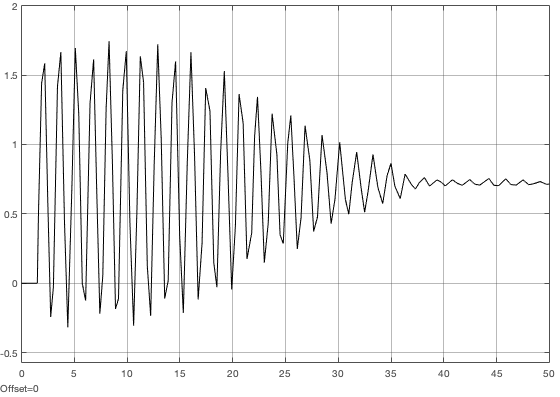


$$k=2\ldotp 75$$


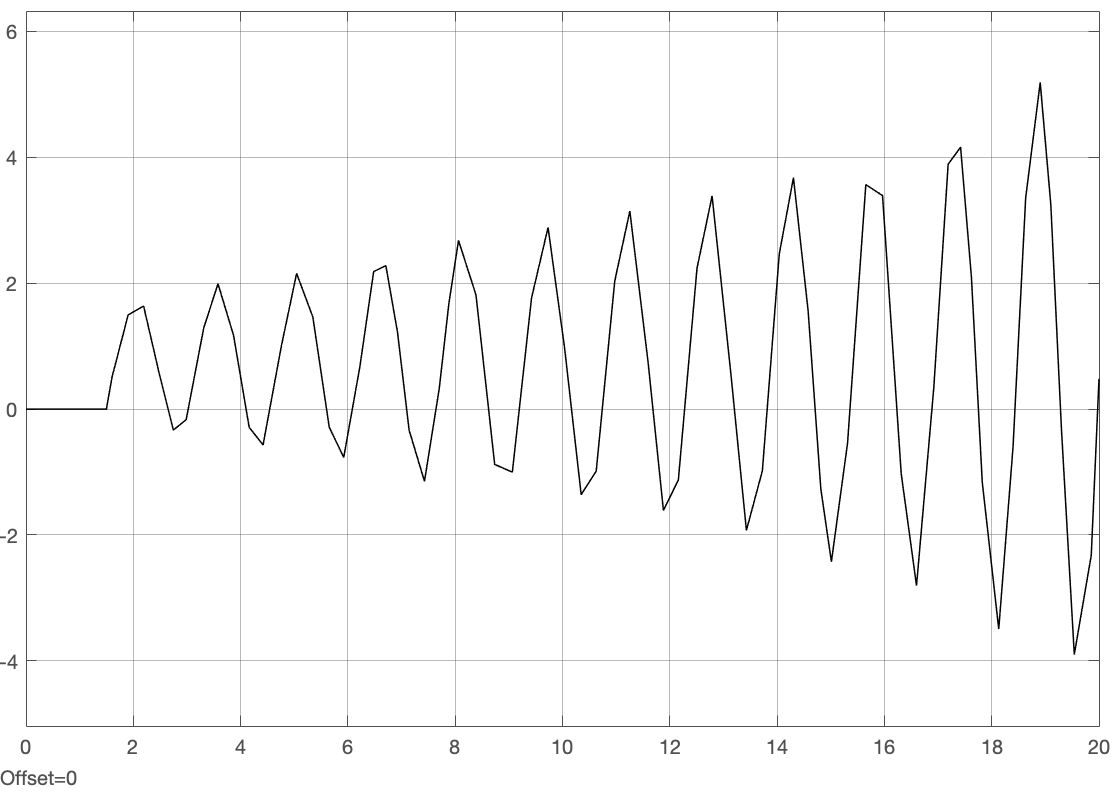

When the input is a sine function:


$$k=-1\ldotp 1$$


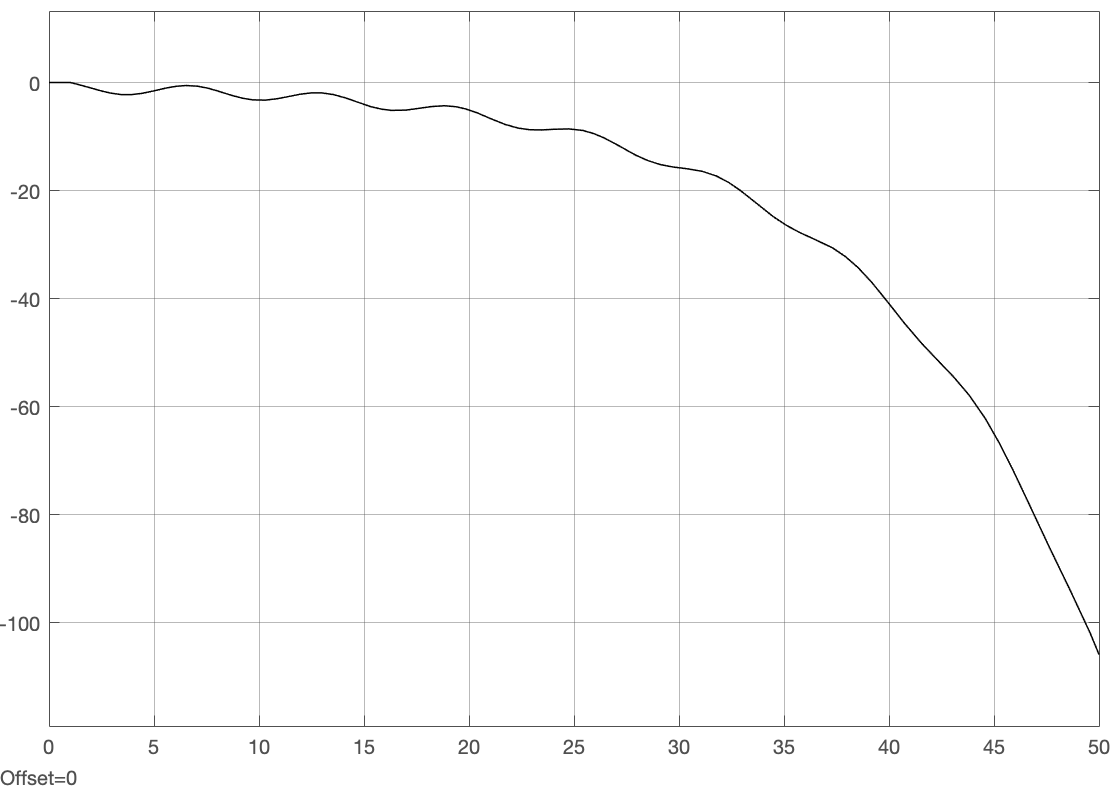


$$k=-0\ldotp 9$$


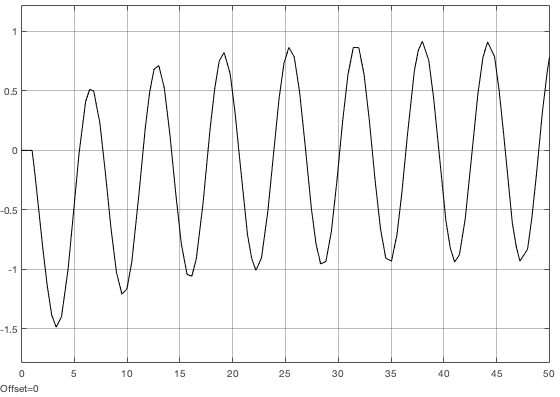


$$k=1$$


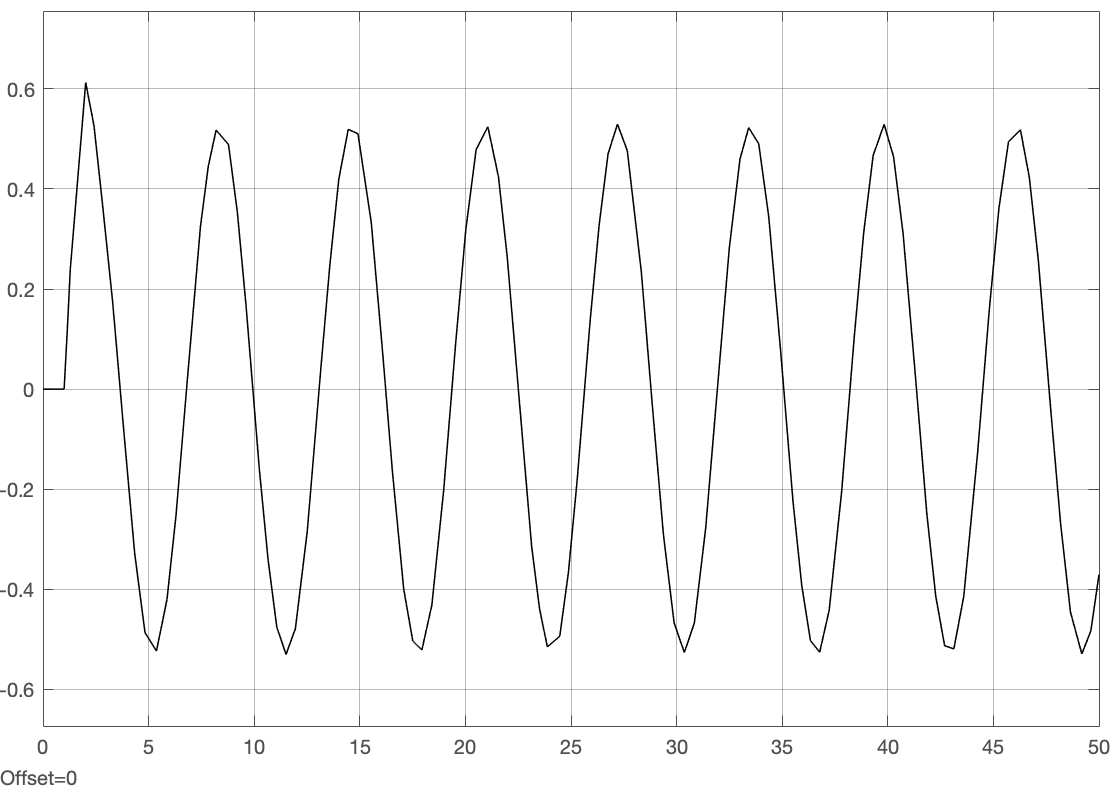


$$k=2\ldotp 2$$


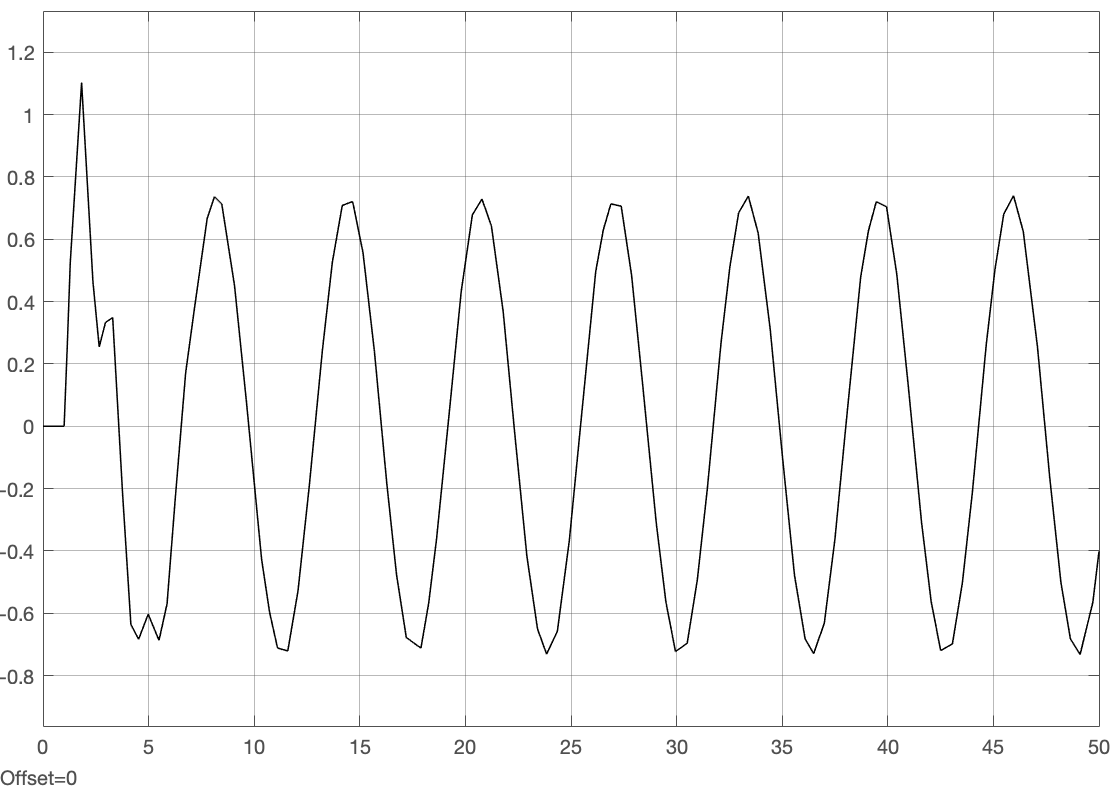


$$k=2\ldotp 6$$


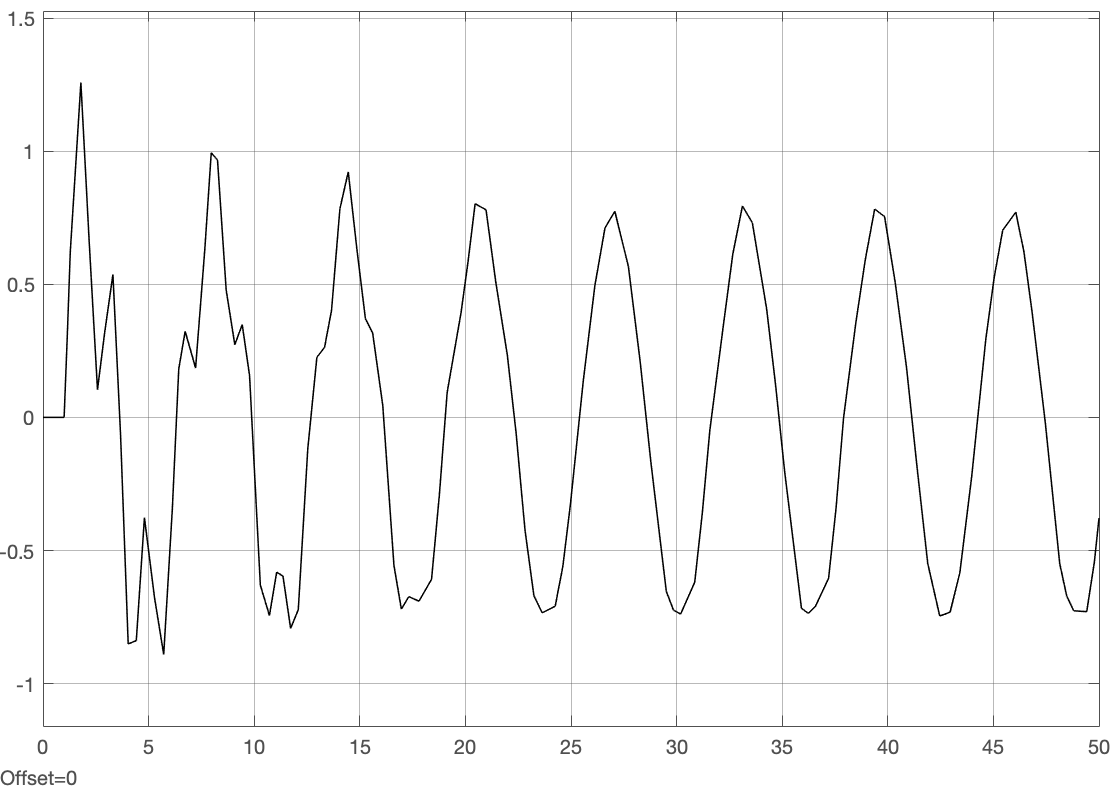


$$k=2\ldotp 75$$


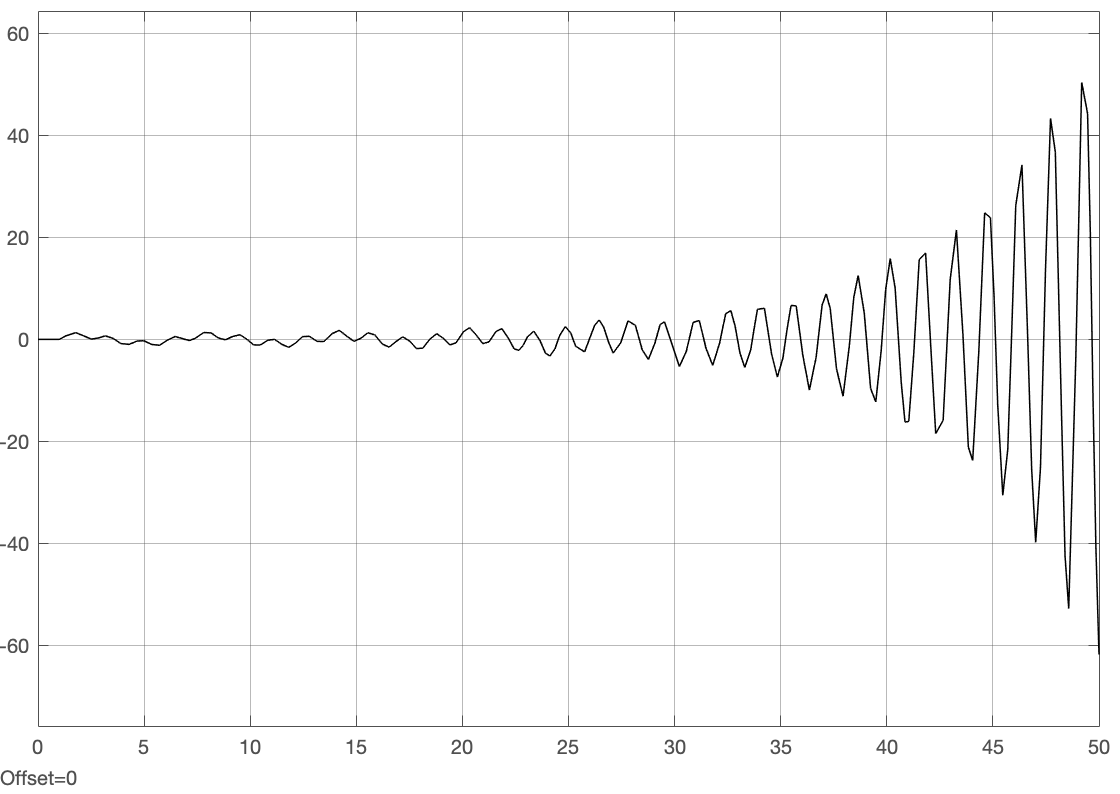

Setting $k=1$ and varying the frequency:

freq = 0.5 rad/s

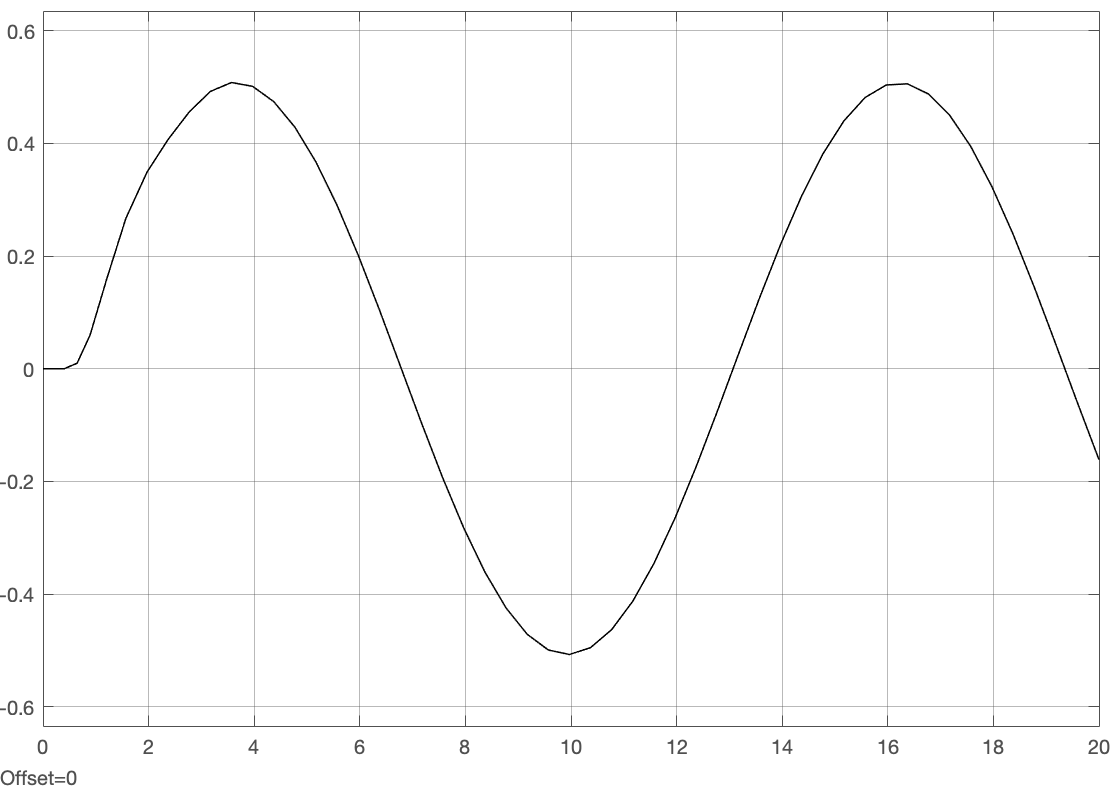

freq = 1 rad/s

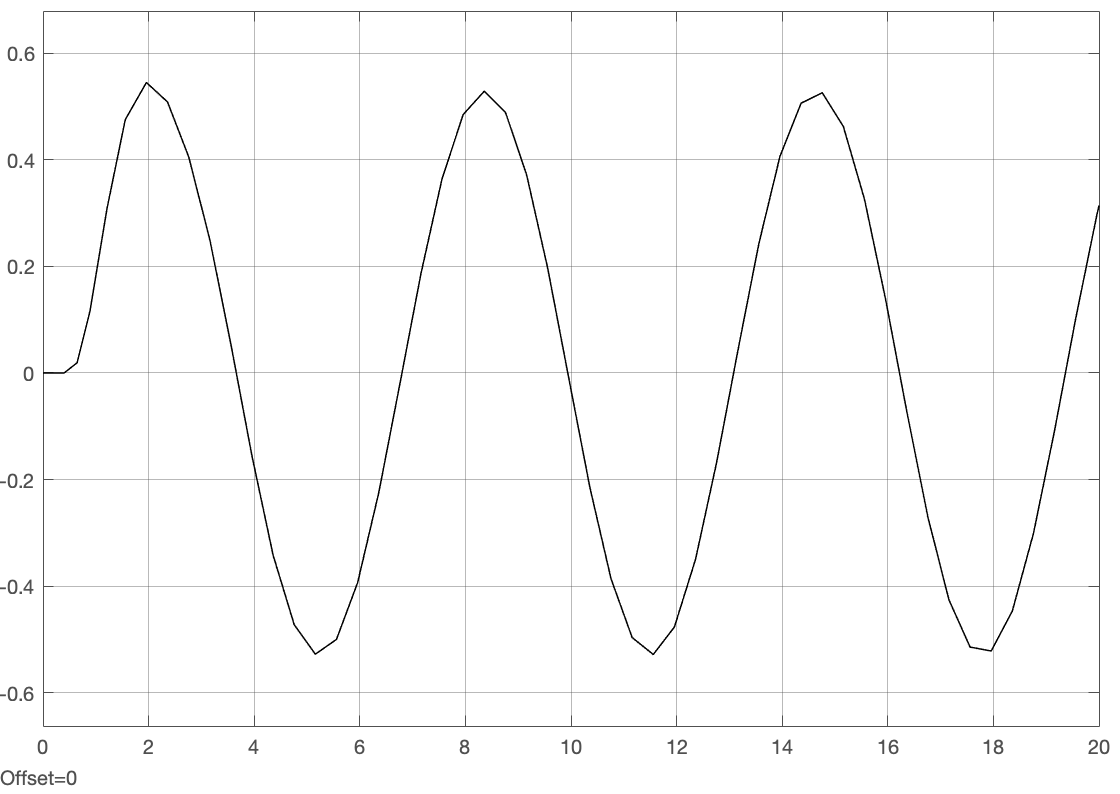

freq = 2 rad/s

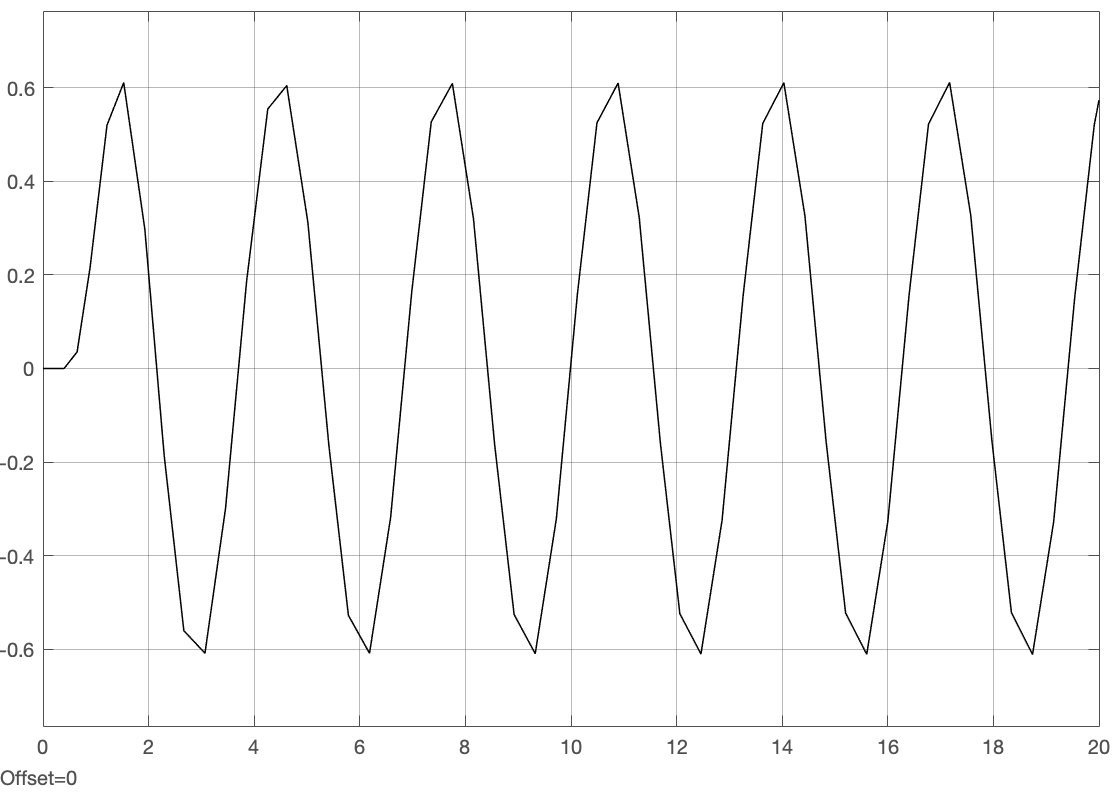

freq = 4 rad/s

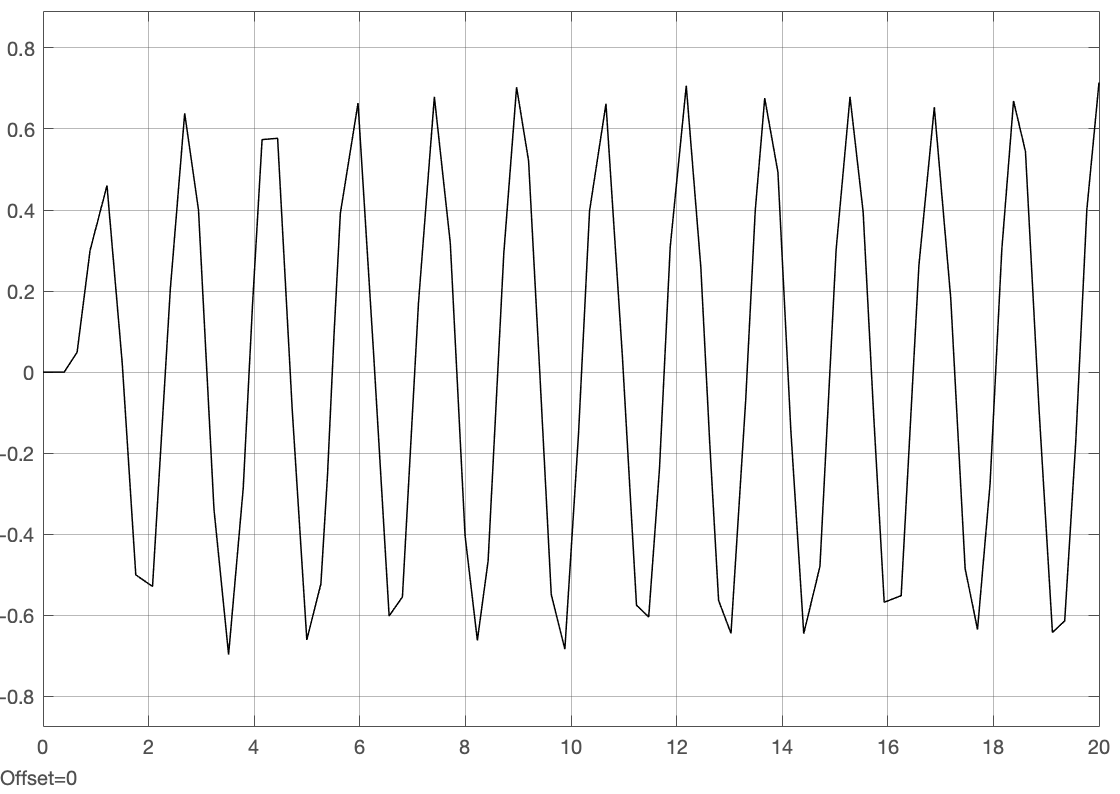

**2.(iii) Replace Transport Delay with Zero-Order Delay**

**2.(iv) Discretize Continuous Plant **$G_0 \left(s\right)$**and apply feedback control **$u=k\left(r-y\right)$

G0 = tf(1, [0.5 1]);
G0_d = c2d(G0, Ts)


G0_d =
 
    0.8647
  ----------
  z - 0.1353
 
Sample time: 1 seconds
Discrete-time transfer function.



Using $G_{0,d} \left(z\right)$in the same Simulink model as 3.2.2 (ii), $k$ was varied to determine if the previous range of $k$leads to stability for the discretized plant too


$$\mathit{\mathbf{r}}=1\left(\mathit{\mathbf{t}}\right)$$


$k=-1\ldotp 1$:

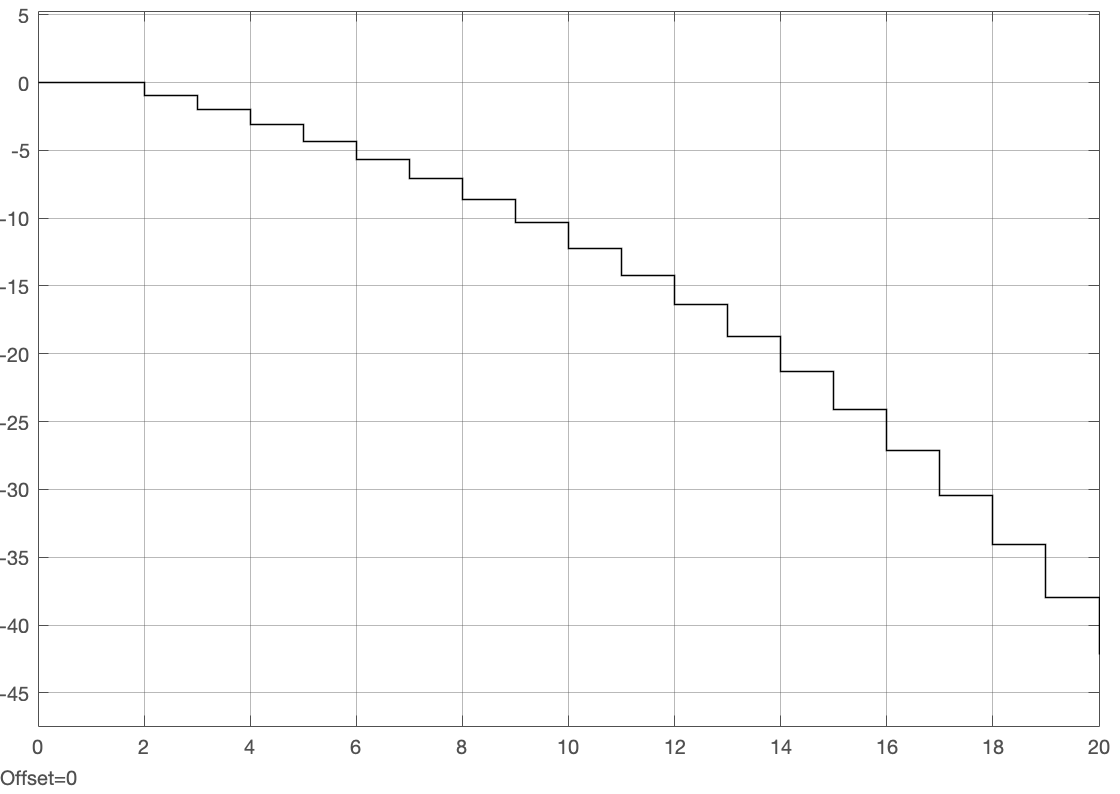


$$k=-0\ldotp 9$$


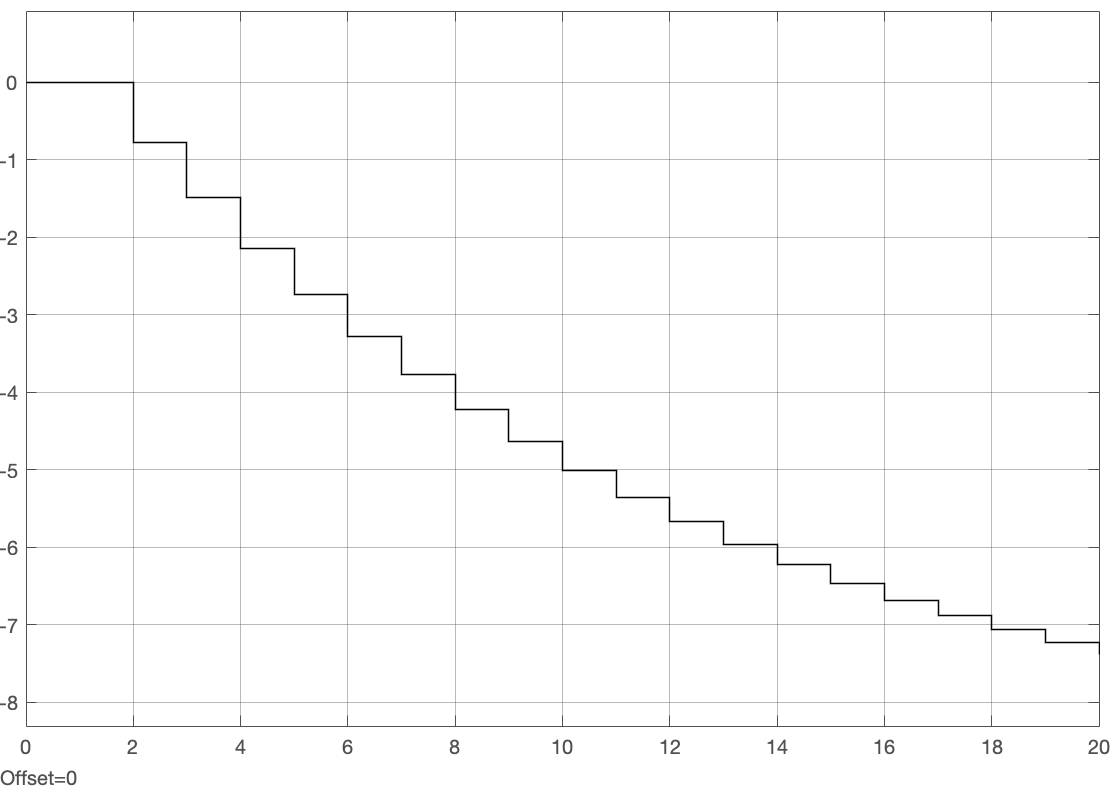


$$k=-0\ldotp 1$$


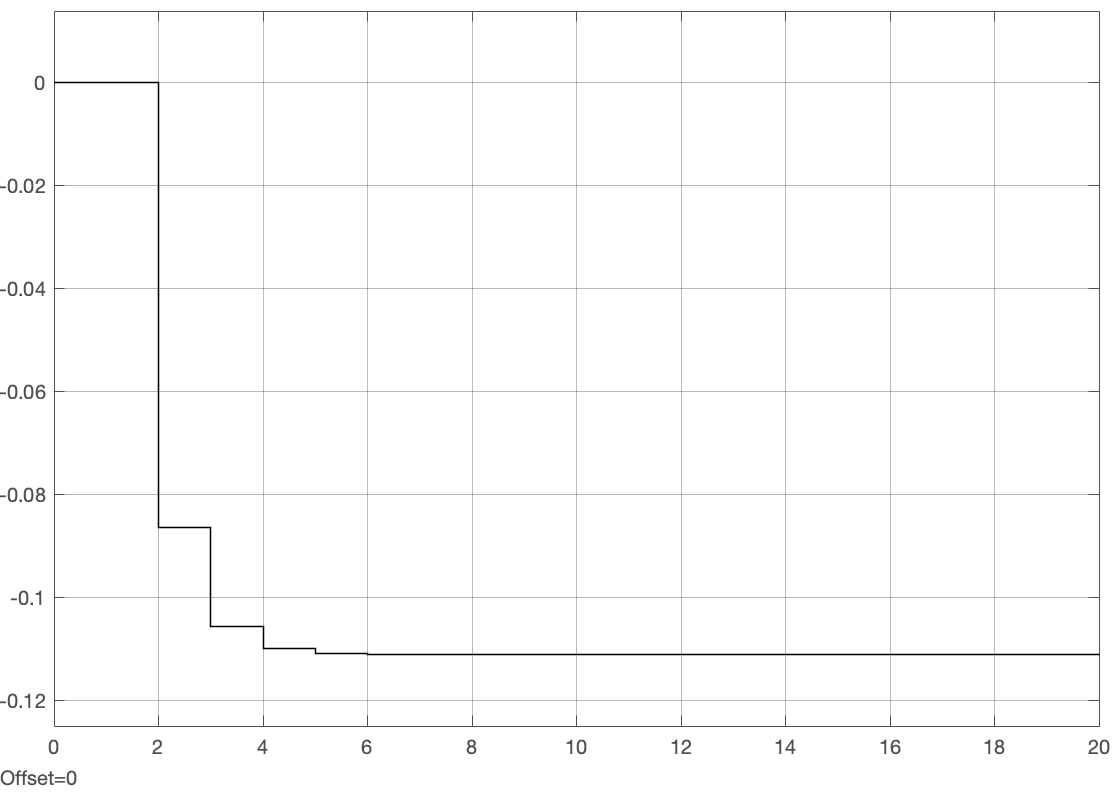


$$k=1$$


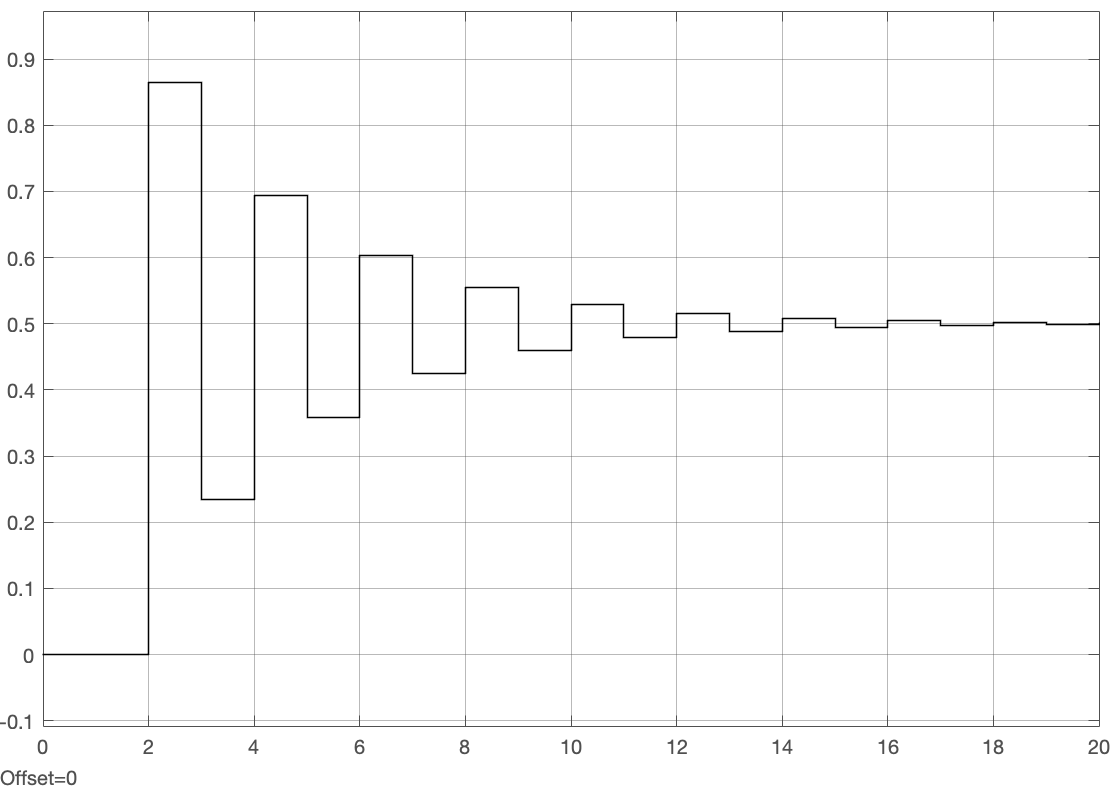


$$k=1\ldotp 3$$


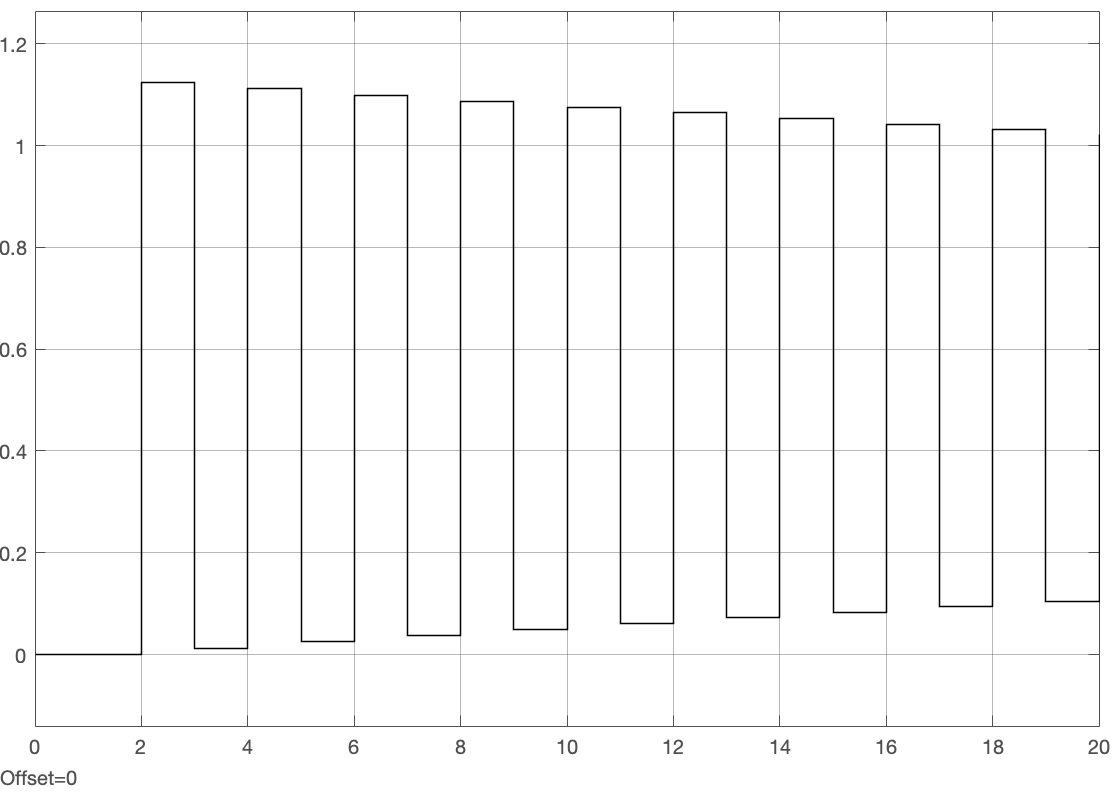


$$k=1\ldotp 375$$


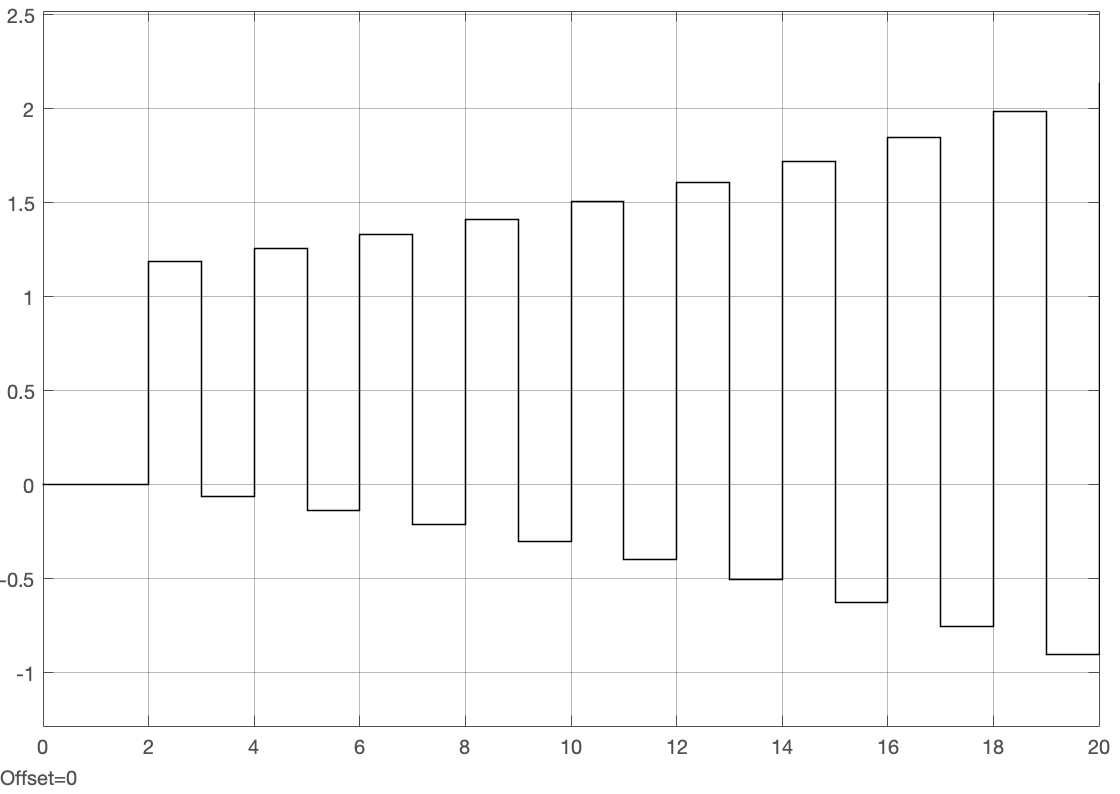

## 3. Intersample Ripple

Ps   = tf(0.1, [1 0.1 0]);
Pd_z = c2d(Ps, Ts);
Cd_z = 9*tf([1 -0.8], [1 0.8], Ts);